clc;
clear;
runtime=250

runtime = 250

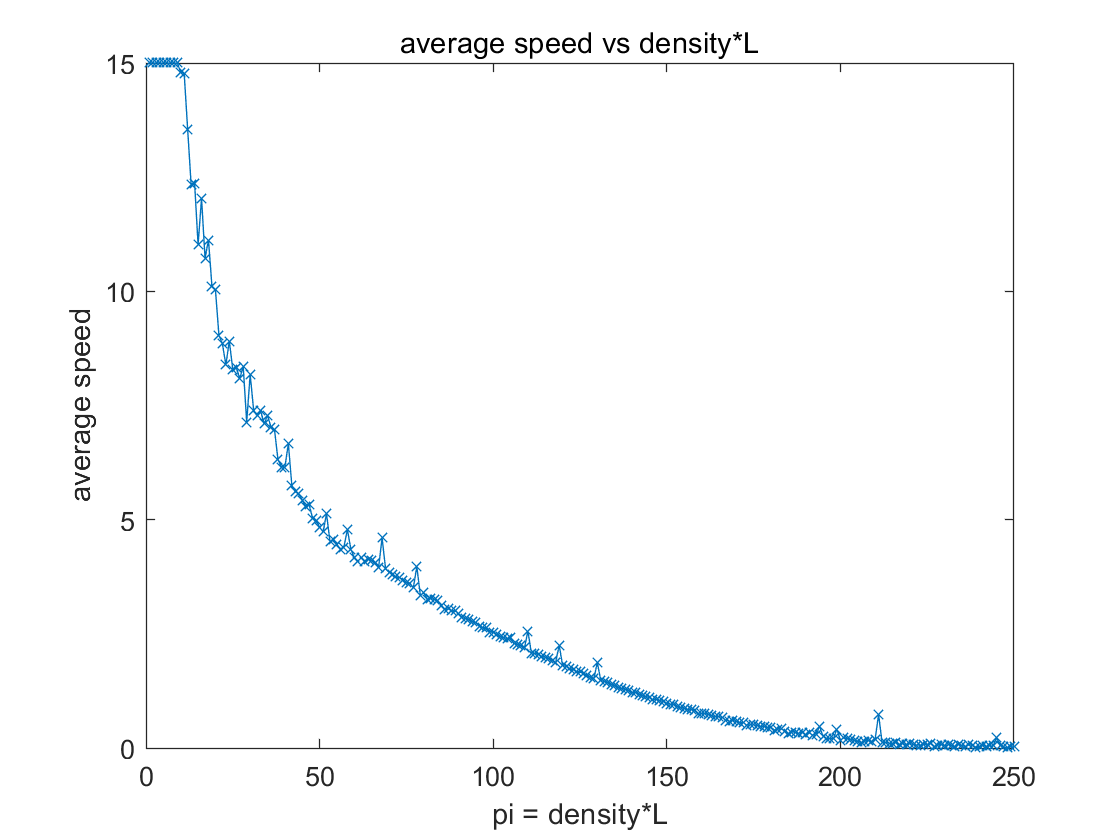

for count=1:runtime
Road_length  =100;
car_number   = count*1;
N(count)=car_number;
acceleration = 6;
deceleration =-6.5;
density(count) = car_number/Road_length;
%initial speed
u = 5;
%time limitis
time =200;
%limit speed
lim = 15;

%repeat loop
for l=1:10
%initial position of car
J = 1:car_number;
A = rand(1,car_number).*Road_length;
x(J,1) =sort(A);
v(J,1)=u;
%minimum distance between cars
x0 = Road_length/car_number;
num = car_number-1;
delT = 0.1;
k = time / delT;
%
average(1) = 0;
t(1) = 0;

for T=2:k
    for J=1:car_number
        if J == car_number
            if J==1
                dis(J,T)= Road_length;
            else
                dis(J,T) = x(1,T-1)-x(J,T-1);
            end
        else
            dis(J,T) = x(J+1,T-1)-x(J,T-1);
        end
        if dis(J,T)<0
            dis(J,T) = Road_length+dis(J,T);
        end
        if dis(J,T) > acceleration * delT
           v(J,T)=v(J,T-1) + acceleration * delT;
        elseif dis(J,T) <= v(J,T-1)
            dis(J,T)=0;
            v(J,T)=0;
        else
           v(J,T)=v(J,T-1)+ deceleration * delT;
        end
        if v(J,T)<0
            v(J,T)=0;
        end
        if v(J,T)>lim
            v(J,T)=lim;
        end
        delta_dis(J,T)=v(J,T)*delT;
        if delta_dis(J,T)>dis(J,T);
            delta_dis(J,T)=dis(J,T);
            v(J,T)=dis(J,T);
        end
        x(J,T)=x(J,T-1)+delta_dis(J,T);
        if x(J,T) > Road_length
           x(J,T)=x(J,T)- Road_length;
        end
    end
      max_speed(T) = max(v(J,T));
      min_speed(T) = min(v(J,T));
      average(T) = sum(v(:,T)) / car_number;
      t(T) = t(T-1) + delT;
end
t(T) = t(T);
x(J,T)=x(J,T);
v(J,T)=v(J,T);
average(T) = average(T);
k_1 = floor(k/2);
d_av = average(1,(k_1):k);
m(l) = mean(d_av);
end
averagespeed(count) = mean(m);
end
plot(N,averagespeed,"-x","MarkerSize",5)
title("average speed vs density*L") 
xlabel('pi = density*L')
ylabel('average speed')